%% TOTO-KORRELAATIOANALYYSI
% Pearson-korrelaatiot: nykytila-featuret vs SIJOITUS (top3)
%                       historia-featuret vs Hist_Sij (kaannetty)
%                       trendi-featuret   vs top3
%
% KOODAUSPERIAATTEET (etumerkki kuvaa ominaisuutta suhteessa nimeensa):
%   Kengat_Etu/Taka:    NO_SHOES=0, HAS_SHOES=1,          UNKNOWN -> NaN
%   Kengat_*_changed:   0=ei muutu, 1=muuttui
%   Special_Cart:       NO=0, YES=1,                       UNKNOWN -> NaN
%   Track_Condition:    heavy=0, quite_heavy=0.33,
%                       winter=0.67, light=1.0,            unknown -> NaN
%   Sukupuoli:          1=Tamma, 2=Ruuna, 3=Ori
%   Valmentaja/Ohjastaja/Rata: nimi -> juokseva ID, Unknown -> NaN
%   km_neg = -Km_aika:  suurempi=nopeampi -> pos.korr intuitiivinen
%   Nopeus_Sij = 16-Hist_Sij+1: korkea=parempi -> pos.korr intuitiivinen
%   Palkinto: suurempi=parempi -> pos.korr intuitiivinen
%   Ennatys_nro: pienempi=nopeampi, arvo 0 -> NaN (puuttuu)

clearvars; clc;

%% -- 1. LATAUS ---------------------------------------------------------------
opts = detectImportOptions('Ravit_Opetus_Data_yhdistetty_v2.csv', 'Delimiter', ';');
opts = setvartype(opts, opts.VariableNames, 'char');
T    = readtable('Ravit_Opetus_Data_yhdistetty_v2.csv', opts);
fprintf('Ladattu %d rivia, %d saraketta.\n\n', height(T), width(T));

Ladattu 79628 rivia, 39 saraketta.



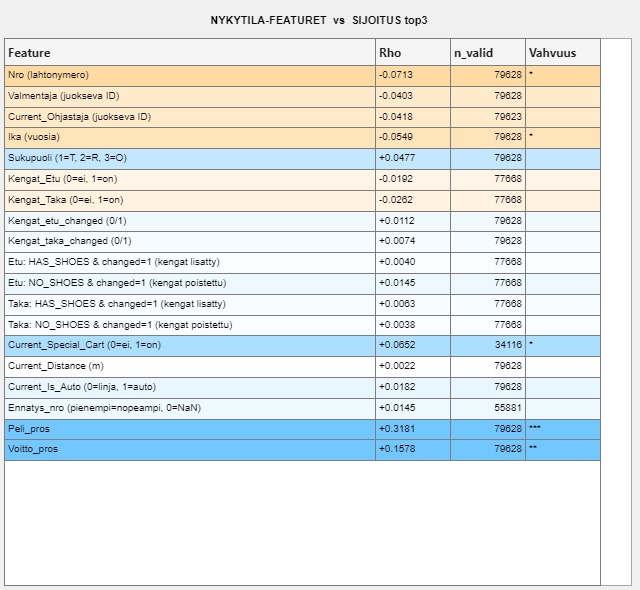


%% -- 2. TARGETIT -------------------------------------------------------------

SIJ       = num(T.SIJOITUS);
top3      = double(SIJ >= 1 & SIJ <= 3);

hylV      = num(T.Hylatty);
kesV      = num(T.Keskeytys);
hsijV     = num(T.Hist_Sij);
validHist = (hsijV >= 1) & (hsijV <= 16) & (hylV == 0) & (kesV == 0);

Nopeus_Sij            = nan(height(T), 1);
Nopeus_Sij(validHist) = 16 - hsijV(validHist) + 1;

%% -- 3. NYKYTILA-FEATURET ----------------------------------------------------

nroV      = num(T.Nro);
ikaV      = num(T.Ika);
sukupV    = num(T.Sukupuoli);
distV     = num(T.Current_Distance);
isAutoV   = num(T.Current_Is_Auto);
peliV     = num(T.Peli_pros);
voittoV   = num(T.Voitto_pros);
ennatysV  = num(T.Ennatys_nro);
ennatysV(ennatysV <= 0) = NaN;

kEtuV    = koodaaKengat(T.Kengat_Etu);
kTakaV   = koodaaKengat(T.Kengat_Taka);
kEtuChV  = num(T.Kengat_etu_changed);
kTakaChV = num(T.Kengat_taka_changed);

etu_has_changed  = nan(height(T), 1);
etu_no_changed   = nan(height(T), 1);
taka_has_changed = nan(height(T), 1);
taka_no_changed  = nan(height(T), 1);
for i = 1:height(T)
    if ~isnan(kEtuV(i))
        etu_has_changed(i)  = double(kEtuV(i)==1 && kEtuChV(i)==1);
        etu_no_changed(i)   = double(kEtuV(i)==0 && kEtuChV(i)==1);
    end
    if ~isnan(kTakaV(i))
        taka_has_changed(i) = double(kTakaV(i)==1 && kTakaChV(i)==1);
        taka_no_changed(i)  = double(kTakaV(i)==0 && kTakaChV(i)==1);
    end
end

specCartV        = koodaaSpecCart(T.Current_Special_Cart);
[valmentajaV, ~] = koodaaNimi(T.Valmentaja);
[currOhjV,    ~] = koodaaNimi(T.Current_Ohjastaja);

%% -- 4. HISTORIA-FEATURET ----------------------------------------------------

[ohjHistV, ~] = koodaaNimi(T.Ohjastaja);
[rataV,    ~] = koodaaNimi(T.Rata);
matkaV        = num(T.Matka);
rataNroV      = num(T.RataNro);
kmV           = num(T.Km_aika);
kmV(kmV <= 0) = NaN;
km_neg        = -kmV;
histIsAutoV   = num(T.Hist_Is_Auto);
laukkaV       = num(T.Laukka);
palkintoV     = num(T.Palkinto);
palkintoV(palkintoV <= 0) = NaN;
kerroV        = num(T.Kerroin);
kerroV(kerroV <= 0) = NaN;
hKEtuV  = koodaaKengat(T.Hist_kengat_etu);
hKTakaV = koodaaKengat(T.Hist_kengat_taka);
hSpecV  = koodaaSpecCart(T.Hist_Special_Cart);
trackV  = koodaaTrack(T.Track_Condition);

%% -- 5. TRENDI-LASKENTA ------------------------------------------------------

MAX_HIST    = 8;
hev_ids     = strcat(T.Nimi, '_', T.RaceID);
uniq_ids    = unique(hev_ids);
N           = numel(uniq_ids);
km_trendi   = nan(N,1); sij_trendi  = nan(N,1);
palk_trendi = nan(N,1); top3_per_hev = nan(N,1);

for u = 1:N
    idx  = find(strcmp(hev_ids, uniq_ids{u}));
    top3_per_hev(u) = top3(idx(1));
    hidx = idx(validHist(idx));
    hidx = hidx(1:min(end, MAX_HIST));
    if numel(hidx) < 2, continue; end
    kvals = kmV(hidx);   ok = ~isnan(kvals);
    if sum(ok)>=2, p=polyfit((1:sum(ok))',kvals(ok),1); km_trendi(u)=p(1); end
    svals = hsijV(hidx); ok = (svals>=1)&(svals<=16);
    if sum(ok)>=2, p=polyfit((1:sum(ok))',svals(ok),1); sij_trendi(u)=p(1); end
    pvals = palkintoV(hidx); ok = ~isnan(pvals);
    if sum(ok)>=2, p=polyfit((1:sum(ok))',pvals(ok),1); palk_trendi(u)=p(1); end
end
km_trendi_neg  = -km_trendi;
sij_trendi_neg = -sij_trendi;

%% -- 6. KORRELAATIOT JA TAULUKOT --------------------------------------------

% {Nimi, x-vektori, y-vektori, kayta_validHist}
nykyF = {
    'Nro (lahtonymero)',                              nroV,            top3, false;
    'Valmentaja (juokseva ID)',                       valmentajaV,     top3, false;
    'Current_Ohjastaja (juokseva ID)',                currOhjV,        top3, false;
    'Ika (vuosia)',                                   ikaV,            top3, false;
    'Sukupuoli (1=T, 2=R, 3=O)',                     sukupV,          top3, false;
    'Kengat_Etu (0=ei, 1=on)',                       kEtuV,           top3, false;
    'Kengat_Taka (0=ei, 1=on)',                      kTakaV,          top3, false;
    'Kengat_etu_changed (0/1)',                       kEtuChV,         top3, false;
    'Kengat_taka_changed (0/1)',                      kTakaChV,        top3, false;
    'Etu: HAS_SHOES & changed=1 (kengat lisatty)',   etu_has_changed, top3, false;
    'Etu: NO_SHOES & changed=1 (kengat poistettu)',  etu_no_changed,  top3, false;
    'Taka: HAS_SHOES & changed=1 (kengat lisatty)',  taka_has_changed,top3, false;
    'Taka: NO_SHOES & changed=1 (kengat poistettu)', taka_no_changed, top3, false;
    'Current_Special_Cart (0=ei, 1=on)',              specCartV,       top3, false;
    'Current_Distance (m)',                           distV,           top3, false;
    'Current_Is_Auto (0=linja, 1=auto)',              isAutoV,         top3, false;
    'Ennatys_nro (pienempi=nopeampi, 0=NaN)',         ennatysV,        top3, false;
    'Peli_pros',                                      peliV,           top3, false;
    'Voitto_pros',                                    voittoV,         top3, false;
};

histF = {
    'Ohjastaja (juokseva ID)',               ohjHistV,    Nopeus_Sij, true;
    'Rata (juokseva ID)',                     rataV,       Nopeus_Sij, true;
    'Matka (m)',                              matkaV,      Nopeus_Sij, true;
    'RataNro',                               rataNroV,    Nopeus_Sij, true;
    'km_neg = -km_aika (suurempi=nopeampi)', km_neg,      Nopeus_Sij, true;
    'Hist_kengat_etu (0=ei, 1=on)',          hKEtuV,      Nopeus_Sij, true;
    'Hist_kengat_taka (0=ei, 1=on)',         hKTakaV,     Nopeus_Sij, true;
    'Hist_Special_Cart (0=ei, 1=on)',        hSpecV,      Nopeus_Sij, true;
    'Hist_Is_Auto (0=linja, 1=auto)',        histIsAutoV, Nopeus_Sij, true;
    'Laukka (0=ei, 1=laukannut)',            laukkaV,     Nopeus_Sij, true;
    'Track_Condition (0=raskas..1=kevyt)',   trackV,      Nopeus_Sij, true;
    'Palkinto (euroa, suurempi=parempi)',    palkintoV,   Nopeus_Sij, true;
    'Kerroin (suurempi=yllattajampi)',       kerroV,      Nopeus_Sij, true;
};

trendiF = {
    'km_trendi_neg (pos=nopeutuu)',       km_trendi_neg,  top3_per_hev, false;
    'sij_trendi_neg (pos=sijoitus par.)', sij_trendi_neg, top3_per_hev, false;
    'palk_trendi (pos=palkinnot kasv.)',  palk_trendi,    top3_per_hev, false;
};

tblNyky   = kokoaTaulukko(nykyF,   validHist);
tblHist   = kokoaTaulukko(histF,   validHist);
tblTrendi = kokoaTaulukko(trendiF, validHist);

%% -- 7. NAYTTO: uitable (vaatii uifigure, ei figure) -------------------------

colNames = {'Feature', 'Rho', 'n_valid', 'Vahvuus'};
colWidth = {370, 75, 75, 75};

f1 = uifigure('Name','Nykytila vs top3','Position',[30 80 640 590]);
uilabel(f1,'Text','NYKYTILA-FEATURET  vs  SIJOITUS top3',...
    'FontSize',11,'FontWeight','bold',...
    'HorizontalAlignment','center',...
    'Position',[0 555 640 30]);
uit1 = uitable(f1,'Data',tblNyky,'ColumnName',colNames,...
    'ColumnWidth',colWidth,'Position',[5 5 628 548],...
    'FontSize',10,'RowName',{},'ColumnSortable',[false true true false]);
coloraaTaulukko(uit1, tblNyky);

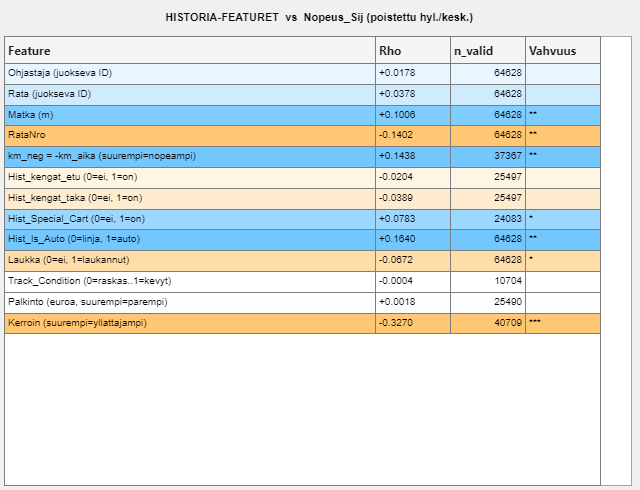


f2 = uifigure('Name','Historia vs Nopeus_Sij','Position',[680 80 640 490]);
uilabel(f2,'Text','HISTORIA-FEATURET  vs  Nopeus_Sij (poistettu hyl./kesk.)',...
    'FontSize',11,'FontWeight','bold',...
    'HorizontalAlignment','center',...
    'Position',[0 458 640 30]);
uit2 = uitable(f2,'Data',tblHist,'ColumnName',colNames,...
    'ColumnWidth',colWidth,'Position',[5 5 628 450],...
    'FontSize',10,'RowName',{},'ColumnSortable',[false true true false]);
coloraaTaulukko(uit2, tblHist);

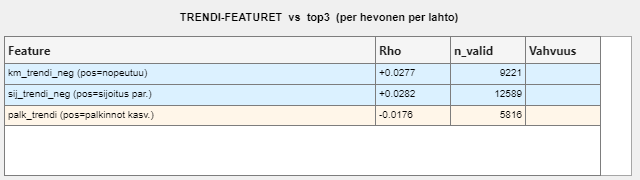


f3 = uifigure('Name','Trendit vs top3','Position',[30 720 640 180]);
uilabel(f3,'Text','TRENDI-FEATURET  vs  top3  (per hevonen per lahto)',...
    'FontSize',11,'FontWeight','bold',...
    'HorizontalAlignment','center',...
    'Position',[0 148 640 30]);
uit3 = uitable(f3,'Data',tblTrendi,'ColumnName',colNames,...
    'ColumnWidth',colWidth,'Position',[5 5 628 140],...
    'FontSize',10,'RowName',{},'ColumnSortable',[false true true false]);
coloraaTaulukko(uit3, tblTrendi);

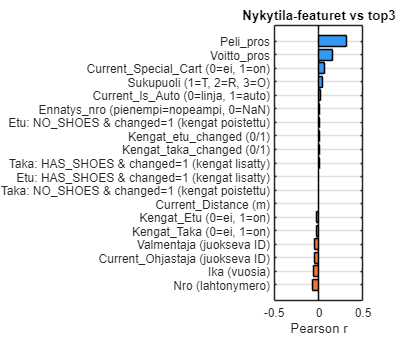


% Pylvaskaaviot (naissa figure on ok)
piirraKaavio(tblNyky, 'Nykytila-featuret vs top3',       [680 560 700 590], [-0.5 0.5]);

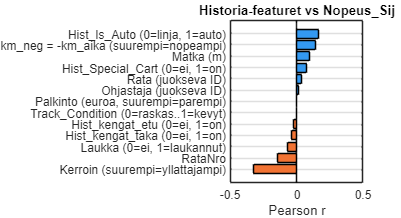

piirraKaavio(tblHist, 'Historia-featuret vs Nopeus_Sij', [30  340 700 380], [-0.5 0.5]);


fprintf('\nValmis! 5 ikkunaa avattu.\n');


Valmis! 5 ikkunaa avattu.


fprintf('Tahdet: empty=|r|<0.05  *=|r|>=0.05  **=|r|>=0.10  ***=|r|>=0.20\n');

Tahdet: empty=|r|<0.05  *=|r|>=0.05  **=|r|>=0.10  ***=|r|>=0.20


fprintf('Taulukoissa: sininen=positiivinen, punainen=negatiivinen korrelaatio.\n');

Taulukoissa: sininen=positiivinen, punainen=negatiivinen korrelaatio.



%% -- APUFUNKTIOT (loppuun) ---------------------------------------------------


function v = num(col)
    v = cellfun(@(x) str2double(strtrim(x)), col);
end

function v = koodaaKengat(col)
    v = nan(numel(col),1);
    for i = 1:numel(col)
        switch upper(strtrim(col{i}))
            case 'HAS_SHOES', v(i)=1;
            case 'NO_SHOES',  v(i)=0;
        end
    end
end

function v = koodaaSpecCart(col)
    v = nan(numel(col),1);
    for i = 1:numel(col)
        switch upper(strtrim(col{i}))
            case 'YES', v(i)=1;
            case 'NO',  v(i)=0;
        end
    end
end

function v = koodaaTrack(col)
    v = nan(numel(col),1);
    for i = 1:numel(col)
        switch lower(strtrim(col{i}))
            case 'heavy track',        v(i)=0.00;
            case 'quite heavy track',  v(i)=0.33;
            case 'winter track',       v(i)=0.67;
            case 'light track',        v(i)=1.00;
        end
    end
end

function [v, kartta] = koodaaNimi(col)
    kartta = containers.Map('KeyType','char','ValueType','double');
    idx=1; v=nan(numel(col),1);
    for i=1:numel(col)
        s=strtrim(col{i});
        if isempty(s)||strcmpi(s,'unknown')||strcmp(s,'0'), continue; end
        if ~isKey(kartta,s), kartta(s)=idx; idx=idx+1; end
        v(i)=kartta(s);
    end
end

function r = nankorr(x, y)
    ok = ~isnan(x) & ~isnan(y);
    if sum(ok)<5, r=NaN; return; end
    xm=x(ok)-mean(x(ok)); ym=y(ok)-mean(y(ok));
    d=sqrt(sum(xm.^2)*sum(ym.^2));
    if d==0, r=NaN; return; end
    r=sum(xm.*ym)/d;
end

function s = tahdet(r)
    if isnan(r), s=''; return; end
    a=abs(r);
    if     a>=0.20, s='***';
    elseif a>=0.10, s='**';
    elseif a>=0.05, s='*';
    else,           s='';
    end
end

function tbl = kokoaTaulukko(F, validHist)
    tbl = cell(size(F,1), 4);
    for k = 1:size(F,1)
        x=F{k,2}; y=F{k,3}; useHist=F{k,4};
        if useHist
            ok = validHist & ~isnan(x) & ~isnan(y);
        else
            ok = ~isnan(x) & ~isnan(y);
        end
        r = nankorr(x(ok), y(ok));
        if isnan(r), rStr='N/A'; else, rStr=sprintf('%+.4f',r); end
        tbl{k,1}=F{k,1}; tbl{k,2}=rStr;
        tbl{k,3}=sum(ok); tbl{k,4}=tahdet(r);
    end
end

function coloraaTaulukko(uit, tbl)
    for k=1:size(tbl,1)
        r=str2double(tbl{k,2});
        if isnan(r)
            c=[0.92 0.92 0.92];
        else
            sat=min(abs(r)*5, 0.55);
            if r>0, c=[1-sat, 1-sat*0.4, 1];
            else,   c=[1, 1-sat*0.4, 1-sat]; end
        end
        addStyle(uit, uistyle('BackgroundColor',c), 'row', k);
    end
end

function piirraKaavio(tbl, otsikko, pos, xlims)
    rhoVec = cellfun(@(s) str2double_safe(s), tbl(:,2));
    [rs,si] = sort(rhoVec,'ascend');
    lbls    = tbl(si,1);
    figure('Name',otsikko,'Position',pos);
    bh = barh(rs,'FaceColor','flat');
    cols=zeros(numel(rs),3);
    for k=1:numel(rs)
        if rs(k)>0, cols(k,:)=[0.2 0.6 0.95];
        else,       cols(k,:)=[0.95 0.45 0.2]; end
    end
    bh.CData=cols;
    yticks(1:numel(lbls)); yticklabels(lbls);
    set(gca,'TickLabelInterpreter','none','FontSize',9);
    xlabel('Pearson r'); title(otsikko,'Interpreter','none');
    xline(0,'k--','LineWidth',1.2); grid on; xlim(xlims);
end

function r = str2double_safe(s)
    r=str2double(s);
    if isnan(r), r=0; end
end